load uspsDigits.mat;
% fix so is uses the centroid of the training data and check vs the test
% data

% centroid metoden (mot 1 centroid)
% fix loop and check tempDiff
%ima(testDigits(:,:,1))

randImgIndex = randi(2007)

randImgIndex = 265

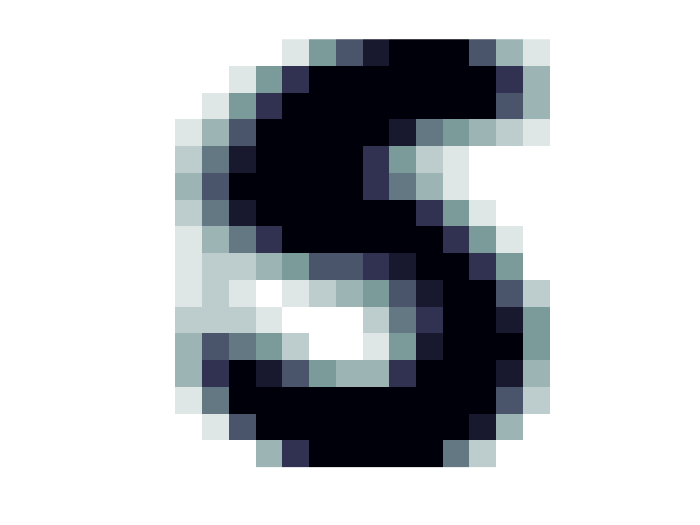


indexDigit = find(testAns == 5);

%mean(testDigits(indexDigit),3)
sumDigit = zeros(16,16,1);
for c = 1:length(indexDigit)
    indexValue = indexDigit(c);
    testDigits(:,:,indexValue);
    sumDigit(:,:,1) = sumDigit(:,:,1) + testDigits(:,:,indexValue);
end
meanDigit = sumDigit./length(indexDigit);
ima(meanDigit)


testAns(randImgIndex)

ans = 8

%tempDiff = abs(norm(meanDigit(:,:,1)) - norm(testDigits(:,:,randImgIndex)))
tempDiff = abs(norm(meanDigit(:,:,1) - testDigits(:,:,randImgIndex))) % this is the right one?

tempDiff = 3.0959

% centroid metoden
randImgIndex = randi(2007)

randImgIndex = 906

results = zeros(10,1);
sumDigit = zeros(16,16,10);
for dig = 0:9
    indexDigit = find(testAns == dig);
    
    for c = 1:length(indexDigit)
        indexValue = indexDigit(c);
        testDigits(:,:,indexValue);
        sumDigit(:,:,dig + 1) = sumDigit(:,:,dig + 1) + testDigits(:,:,indexValue);
    end
    meanDigit = sumDigit./length(indexDigit);
    tempDiff = abs(norm(meanDigit(:,:,dig + 1) - testDigits(:,:,randImgIndex)));
    results(dig + 1) = tempDiff;
end
results

results =     5.3509
    7.1886
    5.2869
    5.3663
    3.9944
    5.1109
    5.5519
    5.4067
    4.8656
    4.8622


[M,I] = min(results);
minDigit = I-1

minDigit = 4

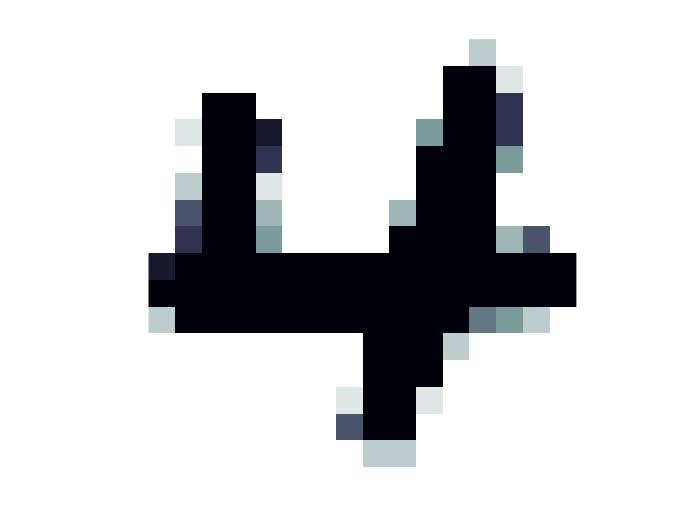

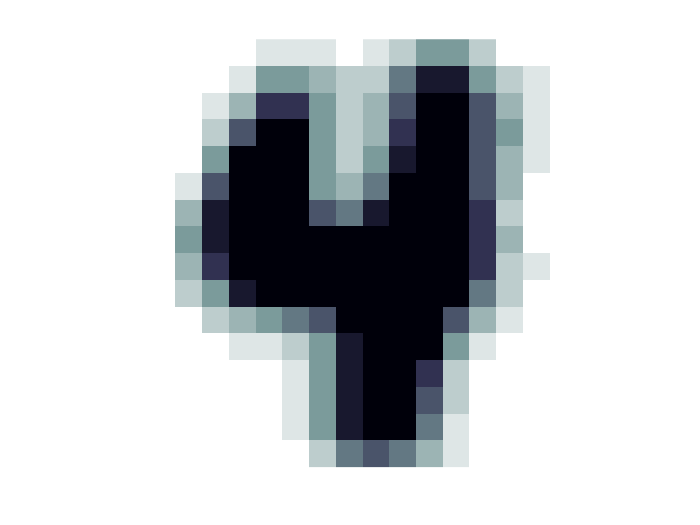

ima(testDigits(:,:,randImgIndex))
ima(sumDigit(:,:,minDigit + 1))

% closest neighbooooor
randImgIndex = randi(2007)

randImgIndex = 1919

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;
for c = 1:2007
    if c ~= randImgIndex
        %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
        tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            savedIndex = c;
        end
    end
end 
savedIndex

savedIndex = 263

savedDiff

savedDiff = 2.0701

testAns(randImgIndex)

ans = 7

testAns(savedIndex)

ans = 7

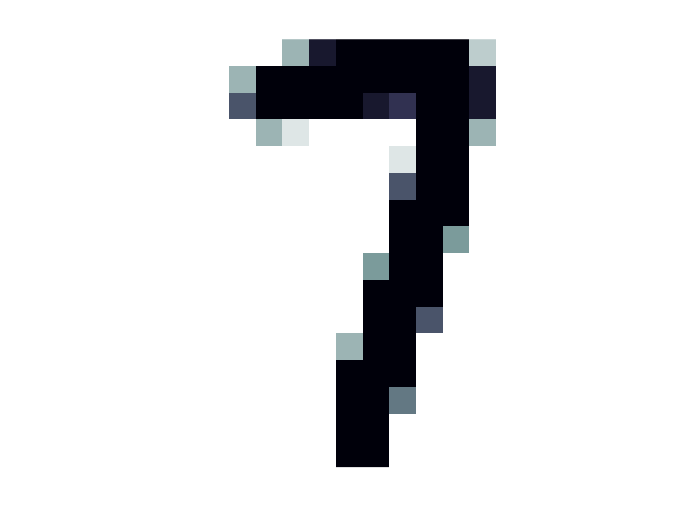

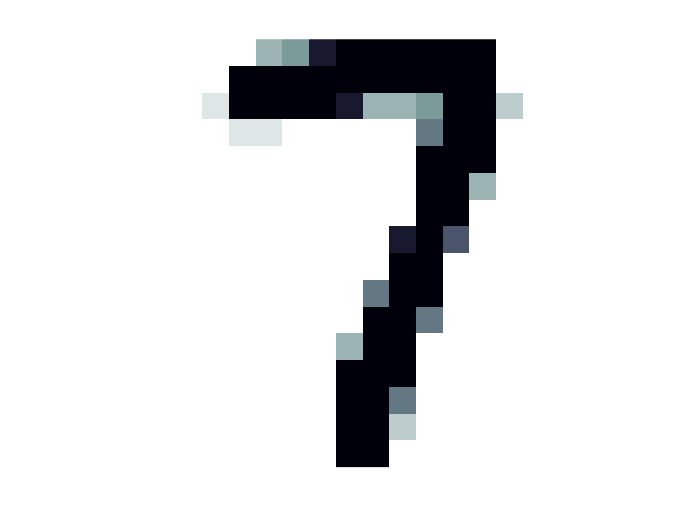

ima(testDigits(:,:,randImgIndex))
ima(testDigits(:,:,savedIndex))

% 5 closest neighbooors 
randImgIndex = randi(2007)

randImgIndex = 1155

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;

nClosesNeighbooorIndex = [0;0;0;0;0];
nClosesNeighbooorValues = [savedDiff;savedDiff;savedDiff;savedDiff;savedDiff];

for n = 1:5
    for c = 1:2007
        if c ~= randImgIndex && c ~= nClosesNeighbooorIndex(1) && c ~= nClosesNeighbooorIndex(2) && c ~= nClosesNeighbooorIndex(3) && c ~= nClosesNeighbooorIndex(4) && c ~= nClosesNeighbooorIndex(5)
            %tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
            tempDiff = abs(norm(kolTestDigits(:,:,c) - kolTestDigits(:,:,randImgIndex)));
            %{
            if tempDiff < nClosesNeighbooorValues(1)
                nClosesNeighbooorValues(1) = tempDiff;
                nClosesNeighbooorIndex(1) = c;
            elseif tempDiff < nClosesNeighbooorValues(2)
                nClosesNeighbooorValues(2) = tempDiff;
                nClosesNeighbooorIndex(2) = c;
            elseif tempDiff < nClosesNeighbooorValues(3)
                nClosesNeighbooorValues(3) = tempDiff;
                nClosesNeighbooorIndex(3) = c;
            elseif tempDiff < nClosesNeighbooorValues(4)
                nClosesNeighbooorValues(4) = tempDiff;
                nClosesNeighbooorIndex(4) = c;
            elseif tempDiff < nClosesNeighbooorValues(5)
                nClosesNeighbooorValues(5) = tempDiff;
                nClosesNeighbooorIndex(5) = c;
            end
            %}
            for j = 1:5
                if tempDiff < nClosesNeighbooorValues(j)
                    nClosesNeighbooorValues(j) = tempDiff;
                    nClosesNeighbooorIndex(j) = c;
                    break;
                end
            end
        end
    end 
end

nClosesNeighbooorIndex

nClosesNeighbooorIndex =         1088
        1190
        1403
         387
         338


testAns(nClosesNeighbooorIndex)

ans =      0
     0
     0
     0
     0


disp(['The most common number is (multiple values occurring equally frequently, ' newline 'mode returns the smallest of those values):'])

The most common number is (multiple values occurring equally frequently, 
mode returns the smallest of those values):


mode(testAns(nClosesNeighbooorIndex))

ans = 0

nClosesNeighbooorValues

nClosesNeighbooorValues =     4.8400
    4.8753
    5.1598
    5.2730
    5.3228


testAns(randImgIndex)

ans = 0